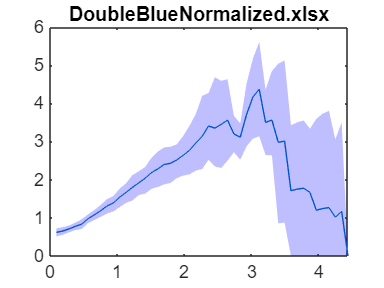

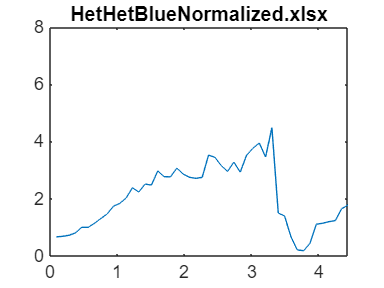

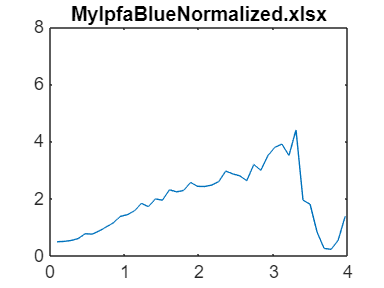

Requested 10000x1048576 (78.1GB) array exceeds maximum array size preference (15.4GB). This might cause MATLAB to become unresponsive.

Error in bootstrp (line 189)
bootstat(nboot,1:numel(bootstat)) = bootstat;

Error in bootci>bootper (line 207)
bstat = bootstrp(nboot,bootfun,varargin{:},'weights',weights,'Options',bootstrpOptions);

Error in 

% Choose Folder to process
clc
clear all
close all

    dirin = uigetdir(title="Select Folder to Process");
    filelist = dir(fullfile(dirin, "*.xlsx"));


for f = 1:length(filelist)
    filein = fullfile(filelist(f).folder, filelist(f).name);

    T = readtable(filein, 'VariableNamingRule',"preserve");
    
    A = table2array(T);
        xes = A(: , 1);
    
    B = table2array(T);
        B(: , 1)= [] ;
        C= mean(B , 2); 

    % calculate confidence intervals via bootstrapping
        meanfun = @(x)mean(x, 1, "omitnan");

    % run bootstrapping 95% CI estimation on transposed C
    dataCI = bootci(10000, {meanfun, B'}, 'Type', 'per');

    % prepare CI data for plottingt
        patchxes = [xes', fliplr(xes')];
        dataPatch = [dataCI(1,:), fliplr(dataCI(2,:))];

    % plot results
    figure()
    plot(xes, C)
    hold on
    patch(patchxes, dataPatch,'b', "FaceAlpha", 0.25, 'LineStyle', 'none')
%     xlabel('X', 'FontSize', 14)
%     ylabel('Y', 'FontSize',14)
    title(filelist(f).name,'Interpreter', 'none')
    %title('Title', 'FontSize', 16)

% save data for later overlay
save([filein(1:end-4), '_with95CI.mat'], 'xes', 'C', 'patchxes', 'dataPatch', '-mat')


% MOVE this *with95CI.mat file outside of the parent folder before
% rerunning this script!


end